cal_data = readtable("data\Calibration table.txt", "Delimiter","\t");

freestream_data = readtable("data\free stream.txt", "Delimiter","\t");
data_4 = readtable("data\4cm.txt", "Delimiter","\t");
data_6 = readtable("data\6cm.txt", "Delimiter","\t");
data_8 = readtable("data\8cm.txt", "Delimiter","\t");
data_9 = readtable("data\9cm.txt", "Delimiter","\t");
data_10 = readtable("data\10cm.txt", "Delimiter","\t");
data_11 = readtable("data\11cm.txt", "Delimiter","\t");
data_12 = readtable("data\12cm.txt", "Delimiter","\t");
data_13 = readtable("data\13cm.txt", "Delimiter","\t");
data_14 = readtable("data\14cm.txt", "Delimiter","\t");
data_15 = readtable("data\15cm.txt", "Delimiter","\t");
data_16 = readtable("data\16cm.txt", "Delimiter","\t");
data_17 = readtable("data\17cm.txt", "Delimiter","\t");
data_19 = readtable("data\19cm.txt", "Delimiter","\t");
data_21 = readtable("data\21cm.txt", "Delimiter","\t");


freestream_avg = mean(freestream_data.U1cal);
avg(:,1) = [4;6;8;9;10;11;12;13;14;15;16;17;19;21];
avg(:,2) = [...
    mean(data_4.U1cal),...
    mean(data_6.U1cal),...
    mean(data_8.U1cal),...
    mean(data_9.U1cal),...
    mean(data_10.U1cal),...
    mean(data_11.U1cal),...
    mean(data_12.U1cal),...
    mean(data_13.U1cal),...
    mean(data_14.U1cal),...
    mean(data_15.U1cal),...
    mean(data_16.U1cal),...
    mean(data_17.U1cal),...
    mean(data_19.U1cal),...
    mean(data_21.U1cal)
    ];

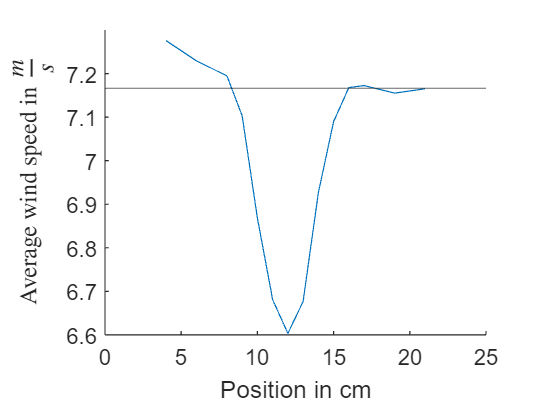

f = figure;
f.Theme = "light";
hold on
plot(avg(:,1), avg(:,2))
yline(freestream_avg);
xlabel("Position in cm");
ylabel("Average wind speed in $\frac{m}{s}$", "Interpreter", "latex");
% saveas(f, "averages.png");